# Frequency Response Function Estimate

%frfest.m
%Birdsong June 2024
%Read experimental data file and overlay estimated TF frequency response plots


## load data


clear %clear all variables from the workspace
load 'bodedata.mat' %loads the experimental frequency response data file
 
format shortG
wp1 = 2.5;
wp2 = 4.5;

mp1 = 10;
mp2 = 1.778;

zeta1 = .06;
zeta2 = .14;

wn1 = wp1/sqrt(1-2*zeta1^2)

wn1 =         2.509


wn2 = wp2/sqrt(1-2*zeta2^2)

wn2 =        4.5909




% 4th order CE
CE1 = [1, 2*zeta1*wn1, wn1^2]

CE1 =             1      0.30109       6.2953


CE2 = [1, 2*zeta2*wn2, wn2^2]

CE2 =             1       1.2854       21.076


num = [10*(wn1^2)*(wn2^2)]

num =        1326.8


den = conv(CE2, CE1)

den =             1       1.5865       27.759       14.438       132.68


## define your estimated open-loop tranfer function here using the TF command


%num=[1]; %define the numerator
%den=[1 1]; %define the denominator (Note this is not the correct TF)
gp=tf(num,den)

gp =
 
                      1327
  ---------------------------------------------
  s^4 + 1.587 s^3 + 27.76 s^2 + 14.44 s + 132.7
 
Continuous-time transfer function.
Model Properties


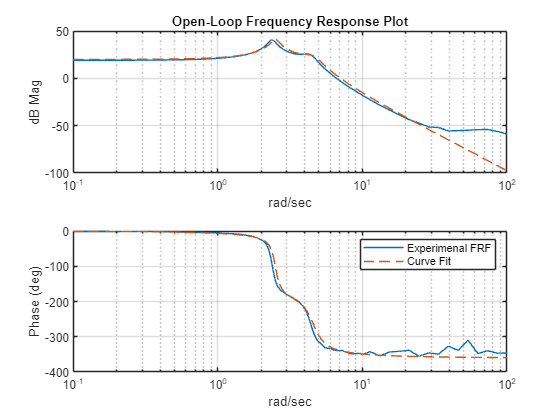

[mmod2,pmod2]=bode(gp,wout);%compute freq resp with w (rad/s) 


%plot the bode diagram
figure(1);subplot(211)
semilogx(wout,20*log10(magdata),wout,20*log10(squeeze(mmod2)),'--');
grid;xlabel('rad/sec');ylabel('dB Mag');
title('Open-Loop Frequency Response Plot');
subplot(212);
semilogx(wout,phasedata,wout,squeeze(pmod2),'--'); 
xlabel('rad/sec');ylabel('Phase (deg)');grid
legend('Experimenal FRF','Curve Fit')

% RL tool

%rltool(gp)


%full state feedback controller
Ts = 0.2;
wn3 = 2.5;
zeta3 = 20/wn3;
wn4 = 4.5;
zeta4 = 20/wn4;

wd3 = wn3*sqrt(1-zeta3^2)

wd3 =             0 +     19.843i


wd4 = wn4*sqrt(1-zeta4^2)

wd4 =             0 +     19.487i


[A B C D] = tf2ss(num,den);
new_poles = [-20+wd3, -20-wd3, -20+wd4, -20-wd4];
K = place(A,B,new_poles)

K =        78.413       3145.7        62926   6.1879e+05


a_cl = A-B*K;
clsys = ss(a_cl,B,C,D)

clsys =
 
  A = 
               x1          x2          x3          x4
   x1         -80       -3174  -6.294e+04  -6.189e+05
   x2           1           0           0           0
   x3           0           1           0           0
   x4           0           0           1           0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
   x4   0
 
  C = 
         x1    x2    x3    x4
   y1     0     0     0  1327
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


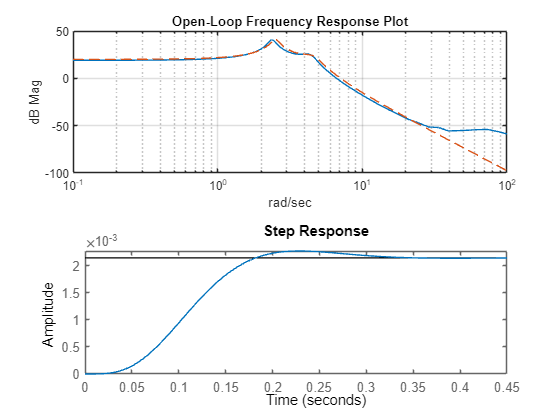

step(clsys)

%LQR
w = 1;
Q = [w 0 0 0;
     0 w 0 0;
     0 0 w 0;
     0 0 0 5000];
R = [1];
[Klqr, S, P]= lqr(A, B, Q, R)

Klqr =        2.0712        4.931       37.263       17.666


S =        2.0712        4.931       37.263       17.666
        4.931       38.268       148.54       339.43
       37.263       148.54       949.86       1231.8
       17.666       339.43       1231.8       5857.4


P =      -0.85264 +     2.4251i
     -0.85264 -     2.4251i
     -0.97623 +     4.6689i
     -0.97623 -     4.6689i


sys1 = ss(A-B*Klqr,B,C,D);
sys1

sys1 =
 
  A = 
           x1      x2      x3      x4
   x1  -3.658  -32.69   -51.7  -150.3
   x2       1       0       0       0
   x3       0       1       0       0
   x4       0       0       1       0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
   x4   0
 
  C = 
         x1    x2    x3    x4
   y1     0     0     0  1327
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


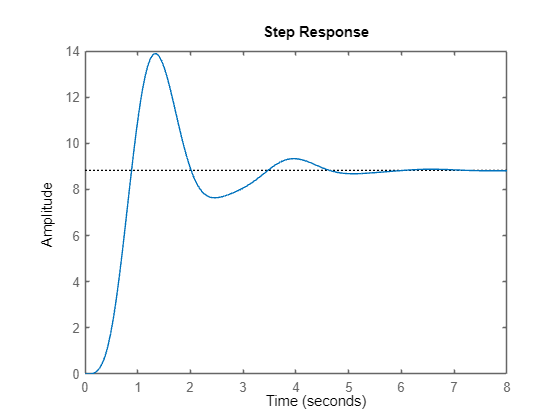

figure()
step(sys1)